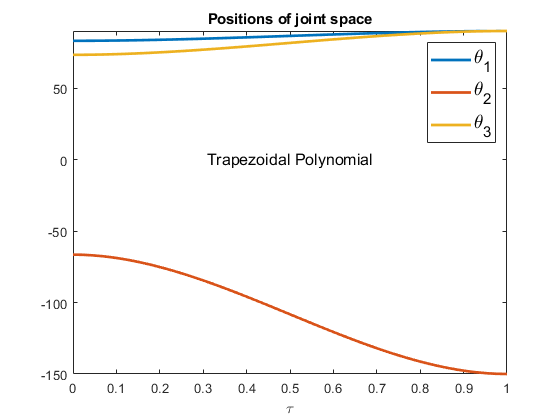

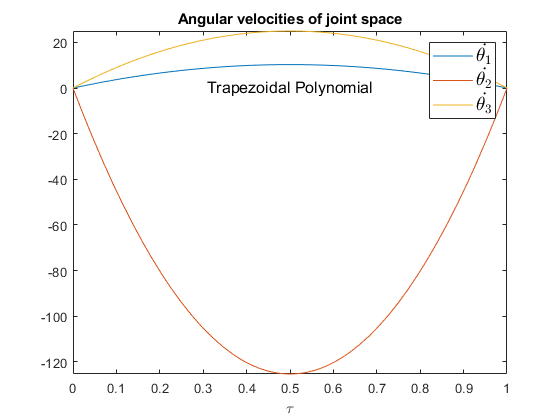

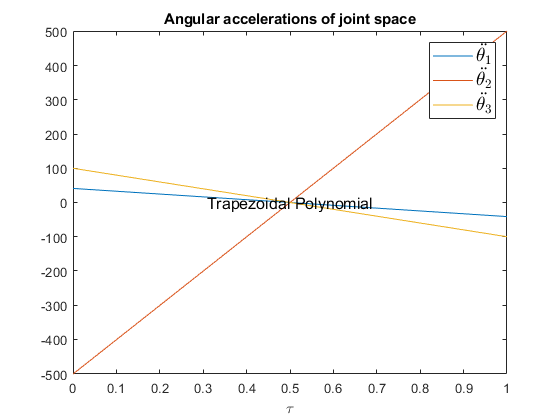

clc, clear
syms tau

th_B = [90, -150, 90];
th_A = [83.14, -66.47, 73.33];
th_C = [173.37, -110, 56.64];

S = 1;      % maximum speed in rad/s
s_trap_soft = -2*tau^3 + 3*tau^2;
s_trap_sharp = 3*S/2*tau^2 - 3*S/2*(tau-1/3)^2 * heaviside(sym(tau - 1/3)) - 3*S/2*(tau - 2/3)^2 * heaviside(sym(tau - 2/3));
s_345 = 6*tau^5 + -15*tau^4 + 10*tau^3;
s_4567 = -20*tau^7 + 70*tau^6 + -84*tau^5 + 35*tau^4;
s_viapose = 27.13*tau^6 - 75.40*tau^5 + 66.40*tau^4 - 17.13*tau^3;

% Trapezoidal Polynomial
angler(th_A, th_B, s_trap_soft, tau, "Trapezoidal Polynomial")

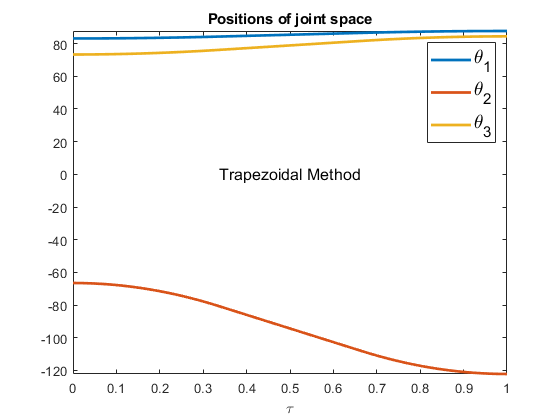

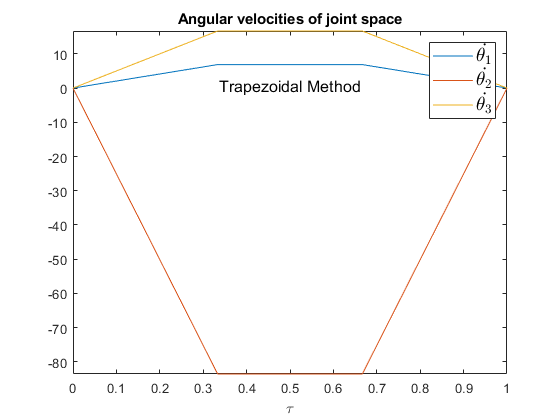

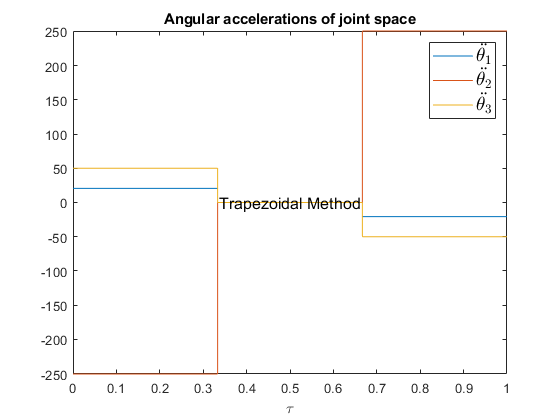


% Trapezoidal Method
angler(th_A, th_B, s_trap_sharp, tau, "Trapezoidal Method")

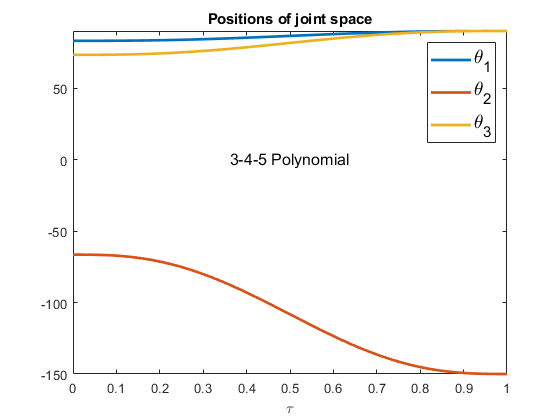

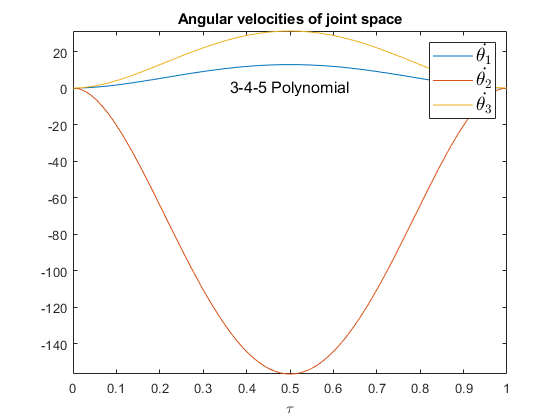

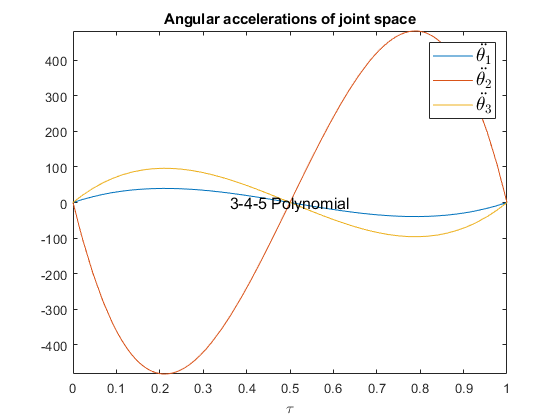


% 3-4-5 Polynomial
angler(th_A, th_B, s_345, tau, "3-4-5 Polynomial")

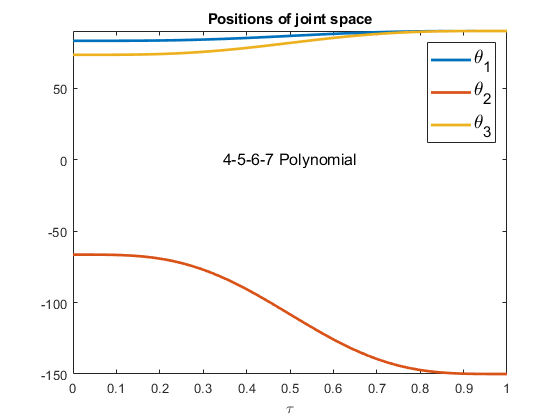

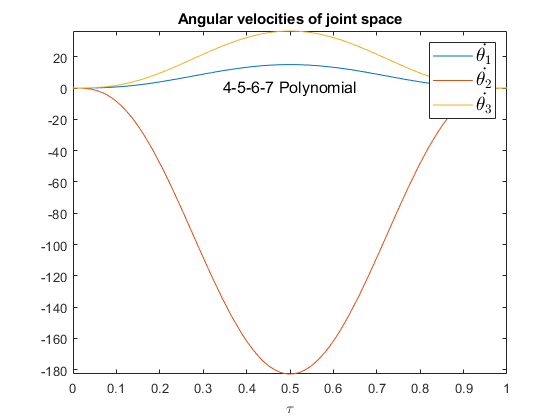

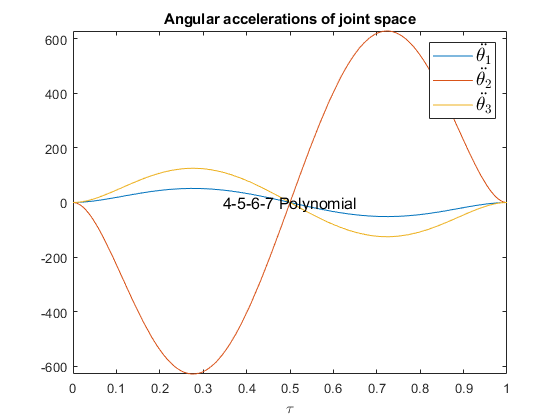


% 4-5-6-7 Polynomial
angler(th_A, th_B, s_4567, tau, "4-5-6-7 Polynomial")

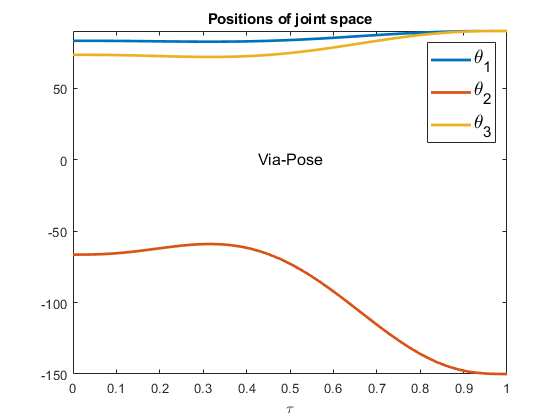

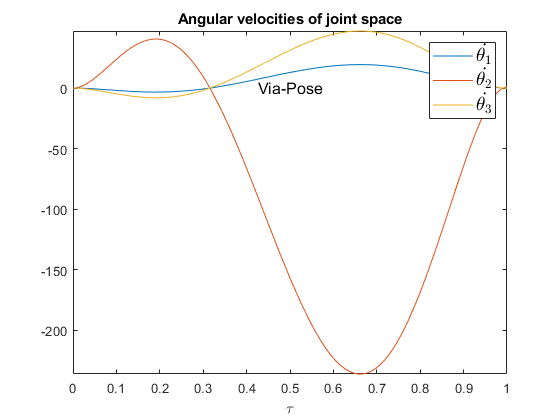

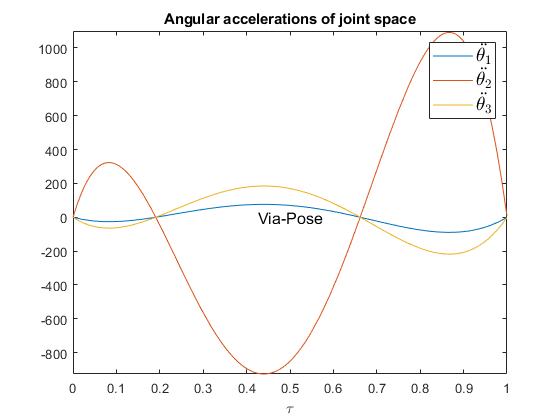


% Via-Pose
angler(th_A, th_B, s_viapose, tau, "Via-Pose")

function [] = angler(start, stop, s_tau, var, name)
set(groot, 'defaultLineLineWidth', 3);
t1 = start(1) + (stop(1) - start(1))*s_tau;
t2 = start(2) + (stop(2) - start(2))*s_tau;
t3 = start(3) + (stop(3) - start(3))*s_tau;

t1_p = diff(t1, var);
t2_p = diff(t2, var);
t3_p = diff(t3, var);

t1_pp = diff(t1_p, var);
t2_pp = diff(t2_p, var);
t3_pp = diff(t3_p, var);

f1 = figure("Name", "position");
fplot(t1, 'LineWidth', 2.0); hold on;
fplot(t2, 'LineWidth', 2.0); hold on;
fplot(t3, 'LineWidth', 2.0); hold on;
legend('\theta_1', "\theta_2", "\theta_3", 'FontSize', 14)   
title("Positions of joint space");
xlabel("\tau")
xlim([0, 1])
ylim('auto')
text(0.5, 1, name, 'HorizontalAlignment', 'center', 'FontSize', 12)

f2 = figure("Name", "velocity");
fplot(t1_p); hold on;
fplot(t2_p); hold on;
fplot(t3_p); hold on;
legend({'$\dot{\theta_1}$', "$\dot{\theta_2}$", "$\dot{\theta_3}$"}, 'Interpreter', 'latex', 'FontSize', 14)   
title("Angular velocities of joint space");
xlabel("\tau")
xlim([0, 1])
ylim([-inf, inf])
text(0.5, 1, name, 'HorizontalAlignment', 'center', 'FontSize', 12)

f3 = figure("Name", "acceleration");
fplot(t1_pp); hold on;
fplot(t2_pp); hold on;
fplot(t3_pp); hold on;
legend({'$\ddot{\theta_1}$', "$\ddot{\theta_2}$", "$\ddot{\theta_3}$"}, 'Interpreter', 'latex', 'FontSize', 14)   
title("Angular accelerations of joint space");
xlabel("\tau")
xlim([0, 1])
ylim([-inf, inf])
text(0.5, 1, name, 'HorizontalAlignment', 'center', 'FontSize', 12)

saveas(f1, "position_"+name+".png")
saveas(f2, "velocity_"+name+".png")
saveas(f3, "acceleration_"+name+".png")
end